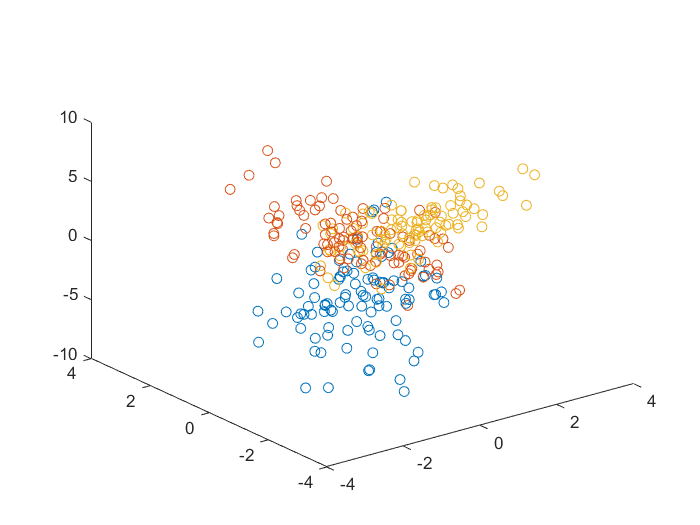

clc; clear; clf;

% 设定均值
mu1 = [-0.8; -0.8];
mu2 = [0; 0];
mu3 = [0.8; -0.8];

% 协方差矩阵
nov1 = [1 0; 0 1];
nov2 = [1 0; 0 1];
nov3 = [1 0; 0 1];

n = 100;
% 生成二元正态分布随机数
figure
hold on
x1 = mvnrnd(mu1, nov1, n);
y1 = -ones(n, 1) + x1(:, 1) + x1(:, 2) + normrnd(0, 1, n, 1);
label1 = 1 * ones(n, 1);
scatter3(x1(:, 1), x1(:, 2), y1)

x2 = mvnrnd(mu2, nov2, n);
y2 = ones(n, 1) - x2(:, 1) + x2(:, 2) + normrnd(0, 1, n, 1);
label2 = 2 * ones(n, 1);
scatter3(x2(:, 1), x2(:, 2), y2)

x3 = mvnrnd(mu3, nov3, n);
y3 = ones(n, 1) + x3(:, 1) - x3(:, 2) + normrnd(0, 1, n, 1);
label3 = 3 * ones(n, 1);
scatter3(x3(:, 1), x3(:, 2), y3)
view(3)


% 绘制二元正态分布散点图
x_data = [x1; x2; x3];
y_data = [y1; y2; y3];
label_data = [label1; label2; label3];

save data1.mat x_data y_data label_data
